## **EXERCISE 3**

% Exercise 3
clc, clearvars, close all

**Task**: forecast the real price of gasoline for the US.

**Dataset**: gasoline.xlsx contains two monthly time series. The nominal price of gasoline and the CPI. 

- Create the real price of gasoline

- Plot real and nominal prices over time

- From now on you will work with logs: yt = log (Real Pricet). Consider the sample from obs 1 to Dec 2014. Plot the sample ACF of yt and that of Dyt = (yt - yt-1).

- Using the same sample above fit two AR(1) models: the first for yt and the second for Dyt. Report in both cases the coefficient associated with the lagged dependent variable.

- Produce a series of 1 step-ahead forecasts for yt. Use the following models: random walk (no drift), ARIMA(1,1,0), ARIMA(0,1,1), ARIMA(1,1,1). To produce forecasts start from the sample that ends in Dec 2014 and add 1 observation at the time (i.e. expanding/recursive scheme)

- Transform the forecasts to levels (i.e. real prices)

- Compute the mean squared forecast error and comment.

data = readtable("gasoline_clean.xlsx");

% Rename variables
data = renamevars(data, ["observation_date", "GASREGW", "CPIAUCSL"], ...
    ["date", "nominal_price", "CPI"]);

% Make it a timetable
data = table2timetable(data);

data(1:6,1:2)

ans = 6×2 timetable
       date        nominal_price     CPI 
    ___________    _____________    _____

    01-Nov-1990        1.324        133.7
    01-Dec-1990        1.341        134.2
    01-Jan-1991         1.18        134.7
    01-Feb-1991       1.0942        134.8
    01-Mar-1991         1.04        134.8
    01-Apr-1991       1.0762        135.1


**1)  Create the real price of gasoline.**

**2) Plot real and nominal prices over time**

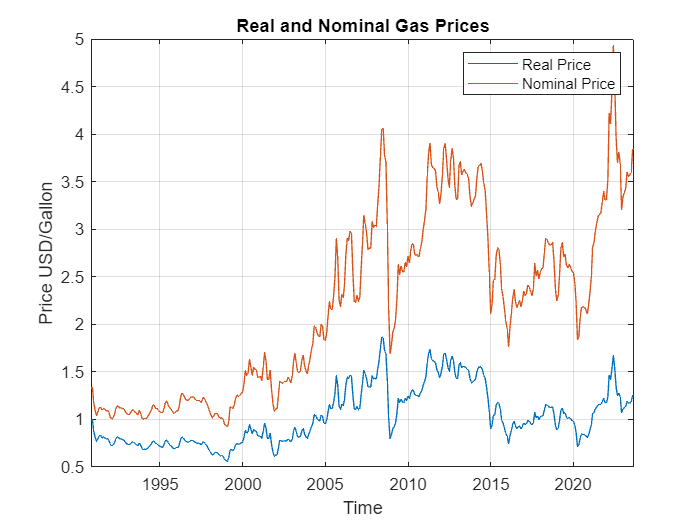

% Real price
data.real_price = (data.nominal_price ./ data.CPI) * 100;

% Plotting the data
figure(1);
plot(data.date, data.real_price, data.date, data.nominal_price);
legend('Real Price', 'Nominal Price');
xlabel('Time');
ylabel('Price USD/Gallon');
title('Real and Nominal Gas Prices');
grid on;

**3) From now on you will work with logs: yt = log (Real Pricet). Consider the sample from obs 1 to Dec 2014. Plot the sample ACF of yt and that of Dyt = (yt - yt-1).**

%% section 3
% log(real_price)
data.log_real_price = log(data.real_price);

% sample data 
sample_data = data(timerange("01-Nov-1990","02-Dec-2014"), :)

sample_data = 290×4 timetable
       date        nominal_price     CPI     real_price    log_real_price
    ___________    _____________    _____    __________    ______________

    01-Nov-1990        1.324        133.7     0.99028        -0.0097708  
    01-Dec-1990        1.341        134.2     0.99925       -0.00074543  
    01-Jan-1991         1.18        134.7     0.87602          -0.13237  
    01-Feb-1991       1.0942        134.8     0.81176          -0.20855  
    01-Mar-1991         1.04        134.8     0.77151           -0.2594  
    01-Apr-1991       1.0762        135.1      0.7966          -0.22741  
    01-May-1991       1.1258        135.6      0.8302          -0.18609  
    01

% from econometrics toolbox
% ACF log real price
[acf, lags] = autocorr(sample_data.log_real_price); 
autocorr(sample_data.log_real_price)

Since the positive and large autocorrelations that slowly decreases, we see the presence of a trend.

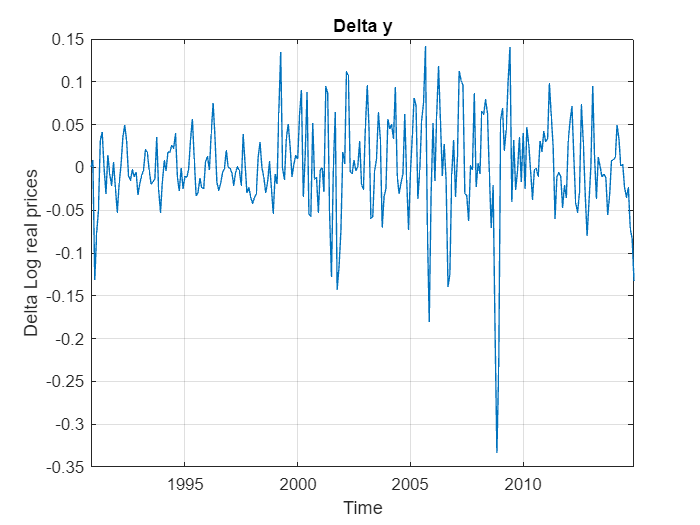

% compute delta_y = (y_t - y_t-1)
time = sample_data.date(2:end);
time = [datetime("01-Nov-1990", 'InputFormat', 'dd-MMM-yyyy'); time]; % add the first date at the beginning to match the series length 
delta_log_rp = diff(sample_data.log_real_price); % compute the difference
delta_log_rp = [0; delta_log_rp]; % add zero value at the beginning to match the series length

sample_data.delta_log_rp = delta_log_rp;
data.delta_log_rp = [0; diff(data.log_real_price)];

plot(sample_data.date, sample_data.delta_log_rp); title('Delta y'); grid on;
xlabel('Time'); ylabel('Delta Log real prices')

% ACF log real price
autocorr(sample_data.delta_log_rp(2:end))


We can see the presence of seasonality inside the series of the Gas prices variation.

**4) Using the same sample above fit two AR(1) models: the first for yt and the second for Dyt. Report in both cases the coefficient associated with the lagged dependent variable**

"Many observed time series exhibit serial autocorrelation; that is, linear association between lagged observations. This suggests past observations might predict current observations. The autoregressive (AR) process models the conditional mean of *yt* as a function of past observations, *yt*−1,*yt*−2,…,*yt*−*p*. An AR process that depends on *p* past observations is called an AR model of degree *p*, denoted by AR(*p*)." 

(source: https://it.mathworks.com/help/econ/specify-ar-models.html)

%% section 4
clc, close all


% Fitting AR(1) model for log real price

mdl_lrp = arima(1, 0, 0); % ARIMA(1,0,0) represents an AR(1) model
est_lrp = estimate(mdl_lrp, sample_data.log_real_price(1:end-1)); % Estimate the model parameters

Unable to resolve the name 'sample_data.log_real_price'.

coef_lrp = est_lrp.AR{1}; % Get the coefficient associated with the lagged dependent variable

[fore,var] = forecast(est_lrp, 105, sample_data.log_real_price(1:end)); % forcasts and var from 01-Dec-2014 to 2023

mean(fore)

 plot(data.date, data.log_real_price', '-b', ...    % plot real values
    data.date, [NaN(1,290), fore'], '-r');          % plot forecast
legend ('Real prices', 'Forecast'); xlabel('Time')
title('AR(1) forecast real gas prices'); grid on

% Fitting AR(1) for delta lrp

mdl_dlrp = arima(1, 0, 0); % ARIMA(1,0,0) represents an AR(1) model
est_dlrp = estimate(mdl_dlrp, sample_data.delta_log_rp(1:end-1)); % Estimate the model parameters
coef_dlrp = est_dlrp.AR{1}; % Get the coefficient associated with the lagged dependent variable

[dfore,dvar] = forecast(est_dlrp, 105, data.delta_log_rp(1:end)); % forcasts and var from 01-Dec-2014 to 2023

mean(dfore)

 plot(data.date, data.delta_log_rp', '-b', ...    % plot real values dlrp
    data.date, [NaN(1,290), dfore'], '-r');          % plot forecast
legend ('Actual dlrp', 'Foreca4st'); xlabel('Time')
title('AR(1) forecast delta gas prices'); grid on


**5)  Produce a series of 1 step-ahead forecasts for yt. Use the following models: random walk (no drift), ARIMA(1,1,0), ARIMA(0,1,1), ARIMA(1,1,1). To produce forecasts start from the sample that ends in Dec 2014 and add 1 observation at the time (i.e. expanding/recursive scheme)**

ARIMA models have three key parameters: the order of autoregression, the degree of differencing and the order of the moving average. These parameters are represented as p, d, and q, respectively.

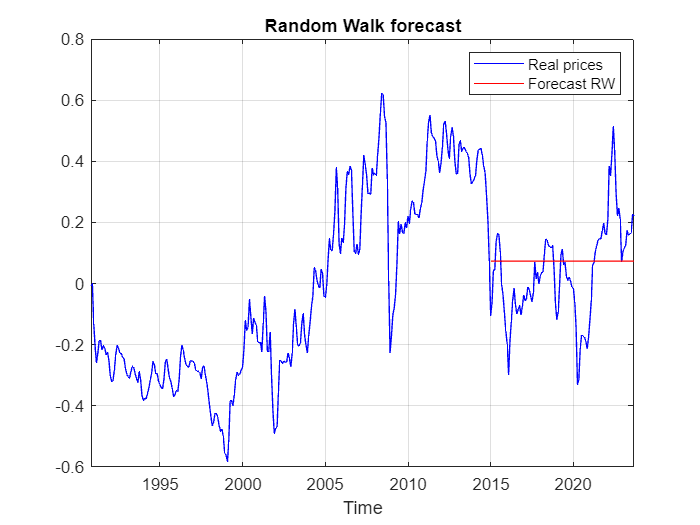

% Random Walk (no drift)
% forcasted values are all equal to y_t(t = "01-Dec-2014")
forecasted_values_RW = [NaN(1, 290), ones(1, 105) * data.log_real_price(290)]; % array of NaN until Dec-2014 (290)


plot(data.date, data.log_real_price', '-b', ...     % plot real prices
    data.date, forecasted_values_RW, '-r');         % plot forcast
title('Random Walk forecast'); legend('Real prices', 'Forecast RW'); xlabel('Time'); grid on

ARIMA(1,1,0)

The series need to be stationary: mean, variance, and autocorrelation structure remain constant over time.

T = height(data); % sample size
T0 = find(data.date=='01-Dec-2014'); % start of estimation sample
h = 1; % forecasthorizon
fore_111 = NaN(T, h); % Tx1 vector to store forecasts for ARIMA(1,1,1)
fore_110 = NaN(T, h); % Tx1 vector to store forecasts for ARIMA(1,1,0)
fore_011 = NaN(T, h); % Tx1 vector to store forecasts for ARIMA(0,1,1)

m_111 = arima('D', 1, 'MA', 1, 'Constant', NaN); % ARIMA(1,1,1) model 

Nonseasonal moving average polynomial is noninvertible.

m_110 = arima('D', 1, 'Constant', NaN); % ARIMA(1,1,0) model
m_011 = arima('D', 1, 'Constant', NaN, 'MALags', 1); % ARIMA(0,1,1) model

jj = T0; % initialize while loop
while jj < T % repeat the following until jj < T
    % ARIMA(1,1,1)
    m_111 = estimate(m_111, data(1:jj)); % estimate ARIMA(1,1,1)
    fore_111(jj+1) = forecast(m_111, h, data(1:jj)); % forecast ARIMA(1,1,1)

    % ARIMA(1,1,0)
    m_110 = estimate(m_110, data(1:jj)); % estimate ARIMA(1,1,0)
    fore_110(jj+1) = forecast(m_110, h, data(1:jj)); % forecast ARIMA(1,1,0)

    % ARIMA(0,1,1)
    m_011 = estimate(m_011, data(1:jj)); % estimate ARIMA(0,1,1)
    fore_011(jj+1) = forecast(m_011, h, data(1:jj)); % forecast ARIMA(0,1,1)

    jj = jj + 1; % increase loop index
end

% forecast errors
uhat_111 = data(T0+1:end) - fore_111(T0+1:end); % forecast errors for ARIMA(1,1,1)
uhat_110 = data(T0+1:end) - fore_110(T0+1:end); % forecast errors for ARIMA(1,1,0)
uhat_011 = data(T0+1:end) - fore_011(T0+1:end); % forecast errors for ARIMA(0,1,1)



ARIMA (0,1,1)

ARIMA (1,1,1)